# Sample 13-3

## 辞書学習

K-特異値分解

画像処理特論

村松 正吾 

動作確認: MATLAB R2023a

## Dictionary learning

K-SVD

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2023a

### 準備

(Preparation)

clear 
close all
import msip.download_img
msip.download_img

kodim01.png already exists in ./data/
kodim02.png already exists in ./data/
kodim03.png already exists in ./data/
kodim04.png already exists in ./data/
kodim05.png already exists in ./data/
kodim06.png already exists in ./data/
kodim07.png already exists in ./data/
kodim08.png already exists in ./data/
kodim09.png already exists in ./data/
kodim10.png already exists in ./data/
kodim11.png already exists in ./data/
kodim12.png already exists in ./data/
kodim13.png already exists in ./data/
kodim14.png already exists in ./data/
kodim15.png already exists in ./data/
kodim16.png already exists in ./data/
kodim17.png already exists in ./data/
kodim18.png already exists in ./data/
kodim19.png already exists in ./data/
kodim20.png already exists in ./data/
kodim21.png already exists in ./data/
kodim22.png already exists in ./data/
kodim23.png already exists in ./data/
kodim24.png already exists in ./data/
See <a href="http://www.r0k.us/graphics/kodak/">Kodak Lossless True Color Image Suite</a

### パラメータ設定

(Parameter settings)

- ブロックサイズ (Block size)

- 冗長率 (Redundancy ratio)

- スパース率 (Sparsity ratio)

- 繰返し回数 (Number of iterations)

% Block size
szBlk = [ 8 8 ];

% Redundancy ratio 
redundancyRatio = 7/3; 

% Sparsity ratio 
sparsityRatio = 3/64;

% Number of iterations
nItersKsvd = 1e3;

## 画像の読込

(Read image)

- 
$$\mathbf{u}\in\mathbb{R}^{N}$$


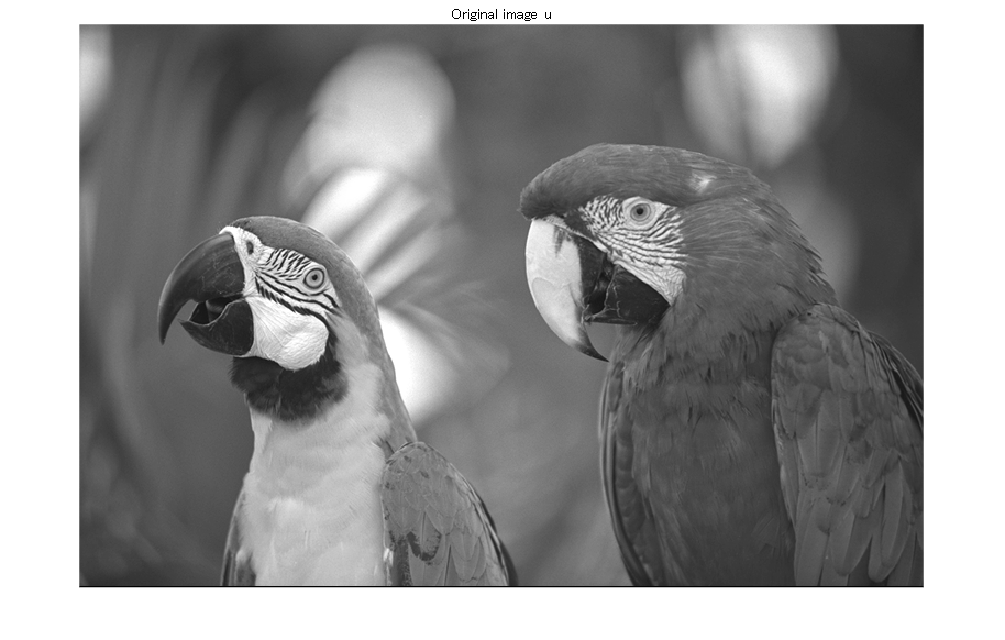

u = rgb2gray(im2double(imread('./data/kodim23.png')));
szOrg = size(u);
figure
imshow(u);
title('Original image u')

#### 画像 $\mathbf{y}$からのデータ行列 $\mathbf{Y}$ の生成 

(Generate data matrices from images )

標本平均ブロックを引く代わりに，予め零平均化したデータで学習(Instead of subtracting the sample average block, training with pre-zero averaged data)

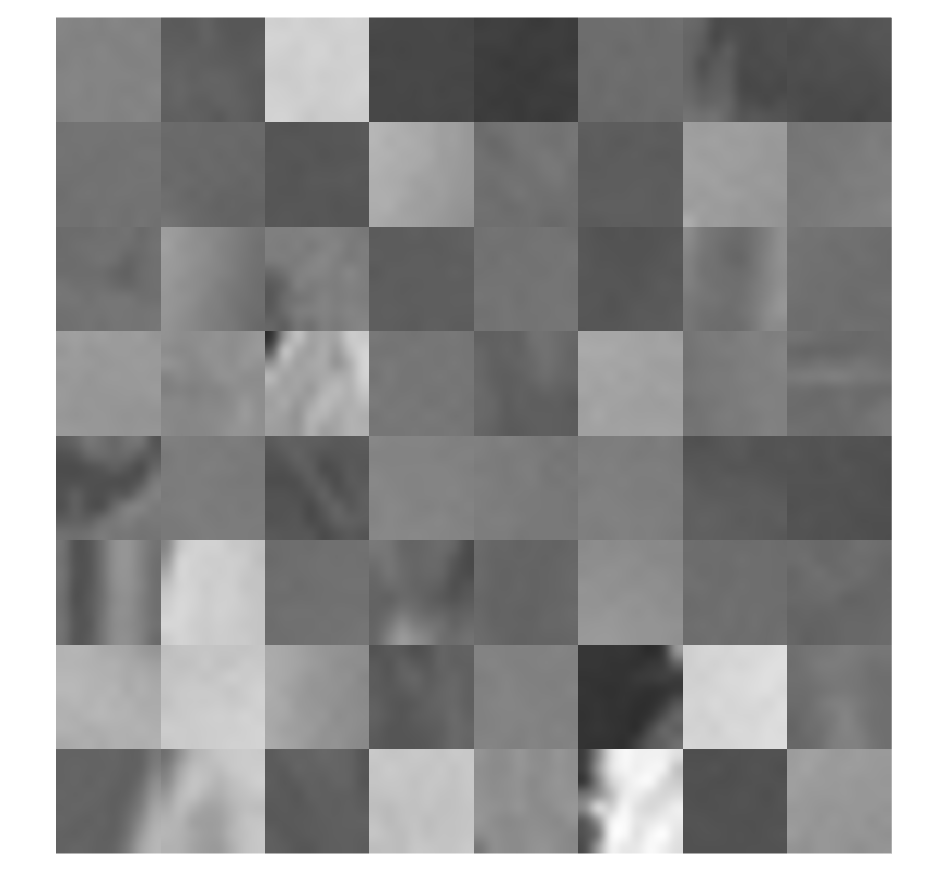

meansubtract = @(x) x-mean(x,"all");
y = meansubtract(u);

% # of patches
nPatches = prod(szOrg./szBlk); 

npos = randsample(prod(szOrg-szBlk),nPatches);
ybs = zeros(szBlk(1),szBlk(2),nPatches,'like',y);
szSrchy = szOrg(1)-szBlk(1);
for iPatch = 1:nPatches
    ny_ = mod(npos(iPatch)-1,szSrchy)+1;
    nx_ = floor((npos(iPatch)-1)/szSrchy)+1;
    ybs(:,:,iPatch) = y(ny_:ny_+szBlk(1)-1,nx_:nx_+szBlk(2)-1);
end
figure
montage(ybs+0.5,'Size',[8 8]);

drawnow

Y = reshape(ybs,prod(szBlk),[]);

### K-特異値分解

 (K-Singular Value Decomposition)

#### 問題設定 (Problem setting):

    
$$\{\hat{\mathbf{\Phi}},\{ \hat{\mathbf{x}}_n \}\}=\arg\min_{\{\mathbf{\Phi},\{\mathbf{x}_n\}\}}\frac{1}{2S}\sum_{n=1}^{S}\|\mathbf{y}_n-\mathbf{\Phi}\hat{\mathbf{x}}_n\|_2^2,\ \quad\mathrm{s.t.}\ \forall n, \|\mathbf{x}_n\|_0\leq K$$$


#### アルゴリズム (Algorithm):

スパース近似ステップと辞書更新ステップを繰返す．

- スパース近似ステップ (Sparse approximation step)

                
$$\hat{\mathbf{x}}_n=\arg\min_{\mathbf{x}_n} \frac{1}{2}\|\mathbf{y}_n-\hat{\mathbf{\Phi}}\mathbf{x}_n\|_2^2\ \quad \mathrm{s.t.}\ \|\mathbf{x}_n\|_0\leq K$$


- 辞書更新ステップ (Dictionary update step)

                
$$\hat{\mathbf{\Phi}}=\arg\min_{\mathbf{\Phi}}\frac{1}{2S}\sum_{n=1}^{S}\|\mathbf{y}_n-\mathbf{\Phi}\hat{\mathbf{x}}_n\|_2^2=\arg\min_{\mathbf{\Phi}}\frac{1}{2S}\left\|\left(\mathbf{Y}-\sum_{p\neq k}\mathbf{\phi}_p\hat{\mathbf{X}}_{p,\colon}\right)-\mathbf{\phi}_k\hat{\mathbf{X}}_{k,\colon}\right\|_F^2$$


係数の数 (Number of coefficients)

要素画像の数 

nDims = prod(szBlk);
nAtoms = ceil(redundancyRatio*nDims);
nCoefsKsvd = max(floor(sparsityRatio*nDims),1);

辞書 $\mathbf{\Phi}$の初期化 (Initializatio of dictionary $\mathbf{\Phi}$)

- 二変量離散コサイン変換(Bivariate DCT)

- ランダム (random)

Phi_ksvd = randn(nDims,nAtoms);
Phi_ksvd = Phi_ksvd/norm(Phi_ksvd,'fro');
for iAtom = 1:nDims
    delta = zeros(szBlk);
    delta(iAtom) = 1;
    Phi_ksvd(:,iAtom) = reshape(idct2(delta),nDims,1);
end

要素ベクトルを要素画像に変換 (Reshape the atoms into atomic images)

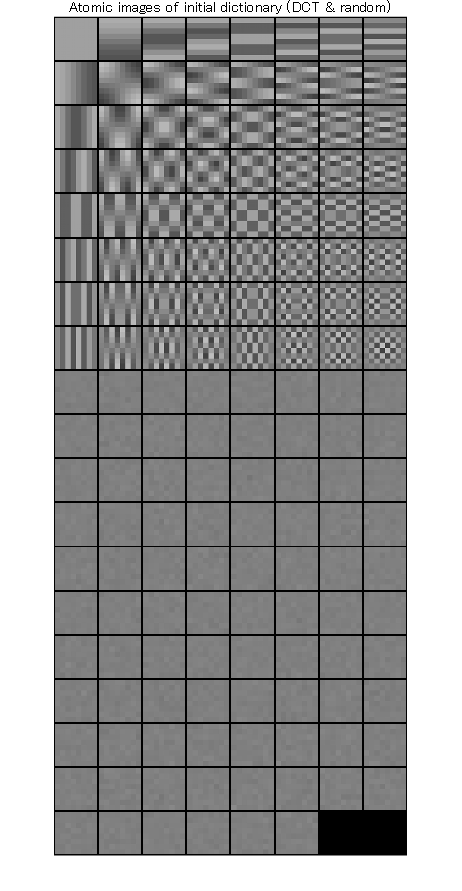

atomicImagesKsvd = zeros(szBlk(1),szBlk(2),nAtoms);
for iAtom = 1:nAtoms
    atomicImagesKsvd(:,:,iAtom) = reshape(Phi_ksvd(:,iAtom),szBlk(1),szBlk(2));
end
figure
montage(imresize(atomicImagesKsvd,8,'nearest')+.5,'BorderSize',[2 2],'Size',[ceil(nAtoms/8) 8])
title('Atomic images of initial dictionary (DCT & random)')

#### スパース近似ステップと辞書更新ステップの繰り返し

- スパース近似： 直交マッチング追跡 (OMP)

- 辞書更新： 特異値分解と1-ランク近似 (SVD and 1-rank approximation)

辞書更新の内容

- 
$$k\leftarrow 1$$


- 誤差行列 $\mathbf{E}_k$ を定義：$\mathbf{E}_k\colon = \mathbf{Y}-\sum_{p\neq k}\mathbf{\phi}_p\hat{\mathbf{X}}_{p,\colon}$

- データ行 $\hat{\mathbf{X}}_{k,\colon}$の非零値を抽出する行列 $\mathbf{\Omega}_k$を定義： $\hat{\mathbf{X}}_{k,\colon}^R=\hat{\mathbf{X}}_{k,\colon}\mathbf{\Omega}_k \Leftrightarrow \hat{\mathbf{X}}_{k,\colon}^R\mathbf{\Omega}_k^T=\hat{\mathbf{X}}_{k,\colon}$

- 誤差行列 $\mathbf{E}_k$ を行列 $\mathbf{\Omega}_k$で縮退： $\mathbf{E}_k^R \colon=\mathbf{E}_k\mathbf{\Omega}_k$

- 縮退した誤差行列$\mathbf{E}_k^R$を特異値分解：$\mathbf{E}_k^R =\mathbf{U}\mathbf{S}\mathbf{V}^T
=\left(\mathbf{u}_1,\mathbf{u}_2,\cdots,\mathbf{u}_r\right)\mathrm{diag}(\sigma_1,\sigma_2,\cdots,\sigma_r)\left(\mathbf{v}_1,\mathbf{v}_2,\cdots,\mathbf{v}_r\right)^T$

- 要素ベクトル $\mathbf{\phi}_k$ を更新： $\mathbf{k}\leftarrow \mathbf{u}_1$

- データ行$\hat{\mathbf{X}}_{k,\colon}$を更新： $\hat{\mathbf{X}}_{k,\colon}\leftarrow \sigma_1\mathbf{v}_{1}^T$

- 
$$k\leftarrow k+1$$


- $k\leq N$ ならば 2. へ $k>N$ ならば終了

ただし， $\sigma_1$ を最大特異値とする．

#### 交互ステップの繰返し計算 (Iterative calculation of alternative steps)

cost = zeros(1,nItersKsvd);
nSamples = size(Y,2);
for iIter = 1:nItersKsvd
    X = zeros(nAtoms,nSamples);
    % Sparse approximation
    for iSample = 1:nSamples
        y_ = Y(:,iSample);
        x = omp(y_,Phi_ksvd,nCoefsKsvd);
        X(:,iSample) = x;
    end
    % Dictionary update
    for iAtom = 1:nAtoms
        idxset = setdiff(1:nAtoms,iAtom);
        xk = X(iAtom,:);
        suppk = find(xk);
        %
        Ekred = Y(:,suppk)-Phi_ksvd(:,idxset)*X(idxset,suppk);
        %
        if ~isempty(suppk)
            [U,S,V] = svd(Ekred,'econ');
            ak = U(:,1);
            xkred = S(1,1)*V(:,1)';
            %
            Phi_ksvd(:,iAtom) = ak;
            X(iAtom,suppk) = xkred;
        end
    end
    cost(iIter) = (norm(Y-Phi_ksvd*X,'fro')^2)/(2*nSamples);
end

コスト評価のグラフ (Graph of cost variation)

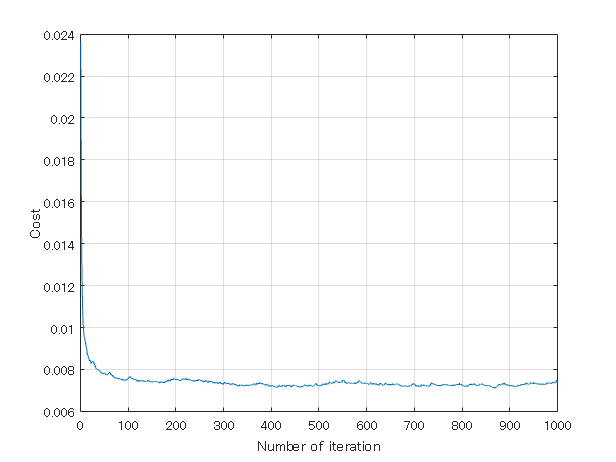

figure
plot(cost)
xlabel('Number of iteration')
ylabel('Cost')
grid on

要素ベクトルを要素画像に変換 (Reshape the atoms into atomic images)

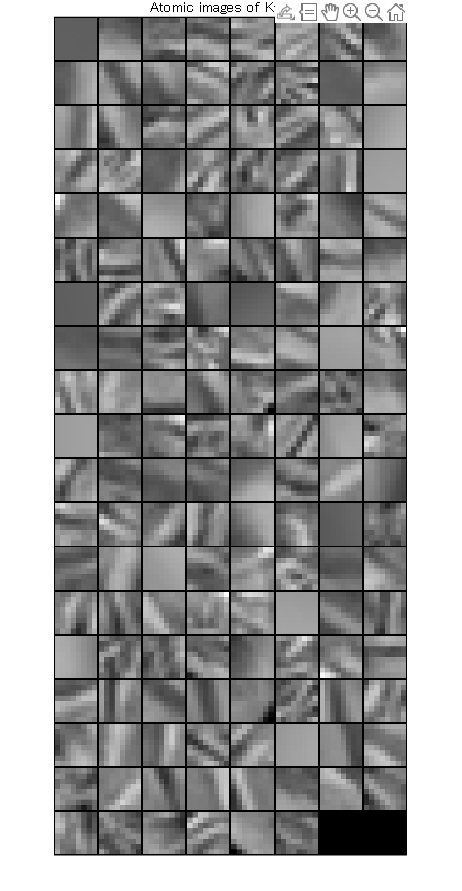

atomicImagesKsvd = zeros(szBlk(1),szBlk(2),nAtoms);
for iAtom = 1:nAtoms
    atomicImagesKsvd(:,:,iAtom) = reshape(Phi_ksvd(:,iAtom),szBlk(1),szBlk(2));
end
figure
montage(imresize(atomicImagesKsvd,8,'nearest')+.5,'BorderSize',[2 2],'Size',[ceil(nAtoms/8) 8])
title('Atomic images of K-SVD')

### 直交マッチング追跡関数 

(Function of orthogonal matching pursuite)

function x = omp(y,Phi,nCoefs)
% Initializaton
nDims = size(Phi,1);
nAtoms = size(Phi,2);
e = ones(nAtoms,1);
a = zeros(nAtoms,1);
g = zeros(nAtoms,1);
x = zeros(nAtoms,1);
v = zeros(nDims,1);
r = y - v;
supp = [];
k = 0;
while k < nCoefs
    % Matching process
    rr = r.'*r;
    for m = setdiff(1:nAtoms,supp)
        d = Phi(:,m);
        g(m) = d.'*r; % γm=<dm,r>
        a(m) = g(m)/(d.'*d); % Normalize αm=γm/||dm||^2
        e(m) = rr - g(m)*a(m); % <r-dm/||dm||^2,r>
    end
    % Minimum value search (pursuit)
    [~,mmin]= min(e);
    % Update the support
    supp = union(supp,mmin);
    subPhi = Phi(:,supp);
    x(supp) = pinv(subPhi) * y;
    % Synthesis process
    v = Phi*x;
    % Residual
    r = y - v;
    % Update
    k = k + 1;
end
end

© Copyright, Shogo MURAMATSU, All rights reserved.